# Getting Started with 4DNvestigator

## 4DNvestigator Overview

### What is the 4DNvestigator

    The 4DNvestigator is a toolbox for analyzing time-series genome-wide chromosome conformation capture (Hi-C) and gene expression (RNA-seq) data.  

### Initial setup of 4DNvestigator Environment

close all, clear all
restoredefaultpath
addpath(genpath(pwd))

### Loading Processed Hi-C and RNA-seq Data

Index_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\myodData\sampleMyodDataIndexTp-48_8_80.xlsx';
Data_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\myodData\';


if exist('sampleMyodDataIndexTp-48_8_80.xlsx','file')==2
    [dataInfo] = fdnLoadUserInput(Index_Loc);
    [H] = fdnLoadHic(Data_Loc,dataInfo,'single');
    [R] = fdnLoadRnaseq(Data_Loc,dataInfo,H);
end

## Example Usage of the 4DNvestigator Tools

### Feature Analyzer

Data_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\myodData\myodData.mat';
Folder_Result = 'results\featureAnalyzerResults';
chrSelect = 11;
dimReduc = 'pca';
binSize = 1E5;
featureAnalyzerExample(Data_Loc, Folder_Result, chrSelect, dimReduc, binSize)

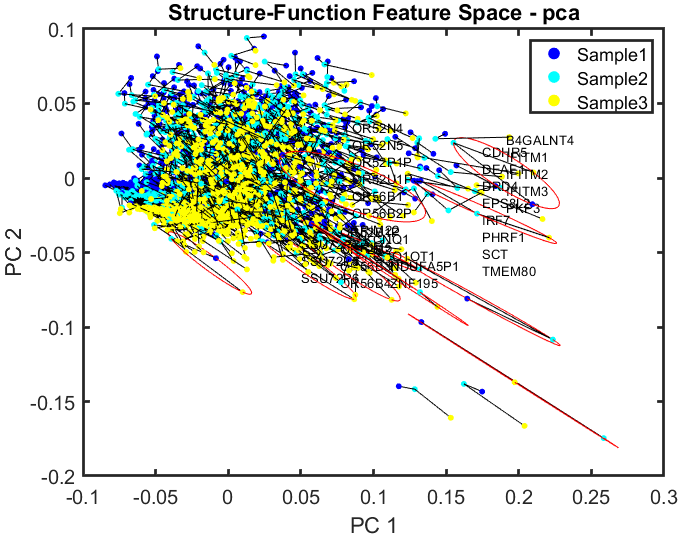

### Von Neumann Entropy

#### Simple Von Neumann Entropy - Two Cell Types

Data_Loc = {'\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\4DNFIFLJLIS5.hic',...
            '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\4DNFIOX3BGNE.hic'};
Folder_Result = 'results\vneExampleResults';
chrSelect = 14;
bpFrag = 'BP';
binSize = 1E5;

vneExample(Data_Loc, Folder_Result, chrSelect, bpFrag, binSize)

    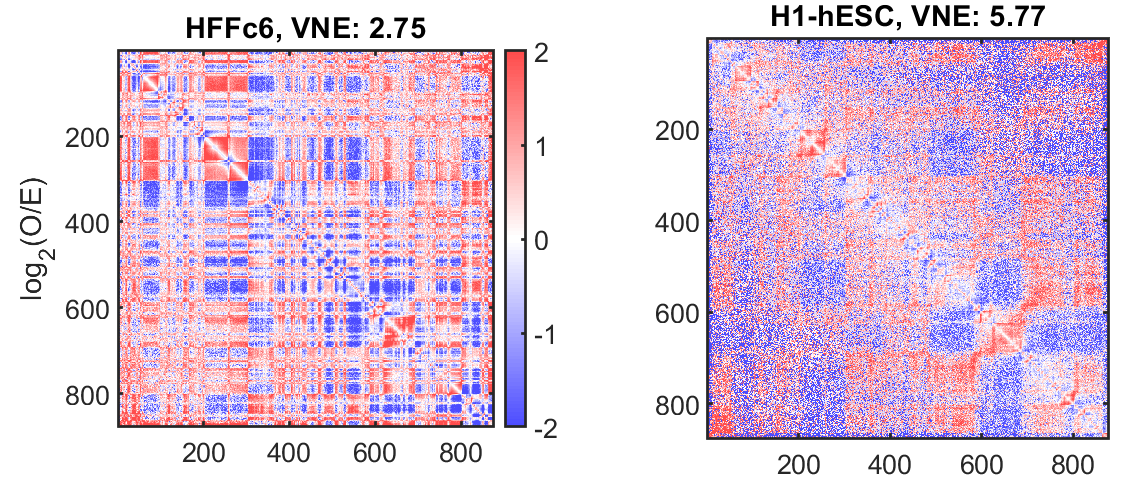

#### Expanded Von Neumann Entropy - Many Cell Types

Data_Loc = {'\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\4DNFIFLJLIS5.hic';...
            '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\4DNFIOX3BGNE.hic';...
            'https://hicfiles.s3.amazonaws.com/hiseq/imr90/in-situ/combined.hic';...
            'https://hicfiles.s3.amazonaws.com/hiseq/huvec/in-situ/combined.hic';...
            'https://hicfiles.s3.amazonaws.com/hiseq/gm12878/in-situ/combined.hic';...
            'http://hicfiles.s3.amazonaws.com/hiseq/rpe1/DarrowHuntley-2015/WT-combined.hic'};
Folder_Result = 'results\vneExampleExpandedResults';
chrSelect = 14;
bpFrag = 'BP';
binSize = 1E5;

vneExampleExpanded(Data_Loc, Folder_Result, chrSelect, bpFrag, binSize)

    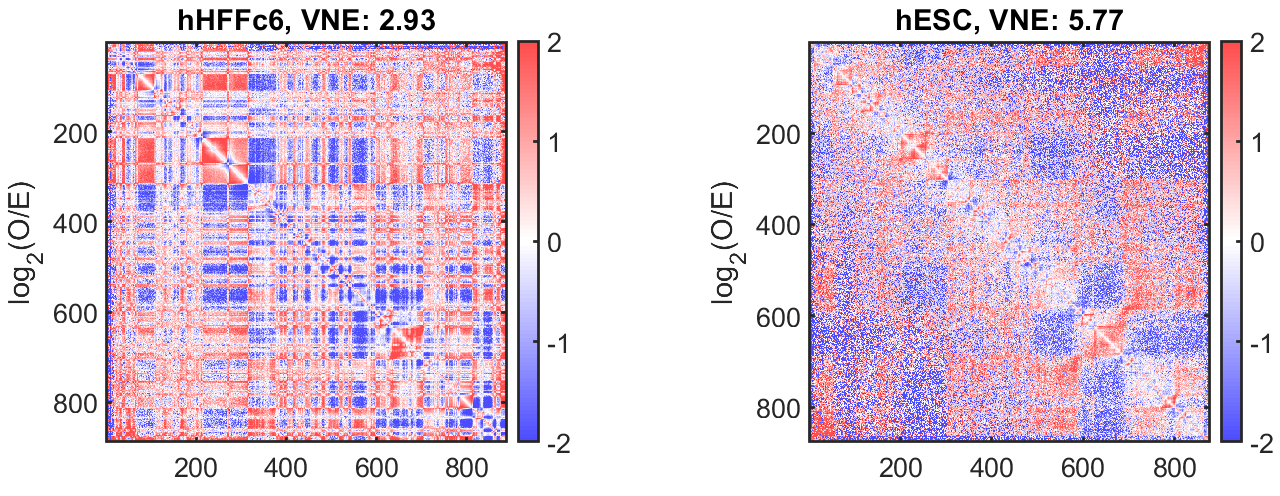

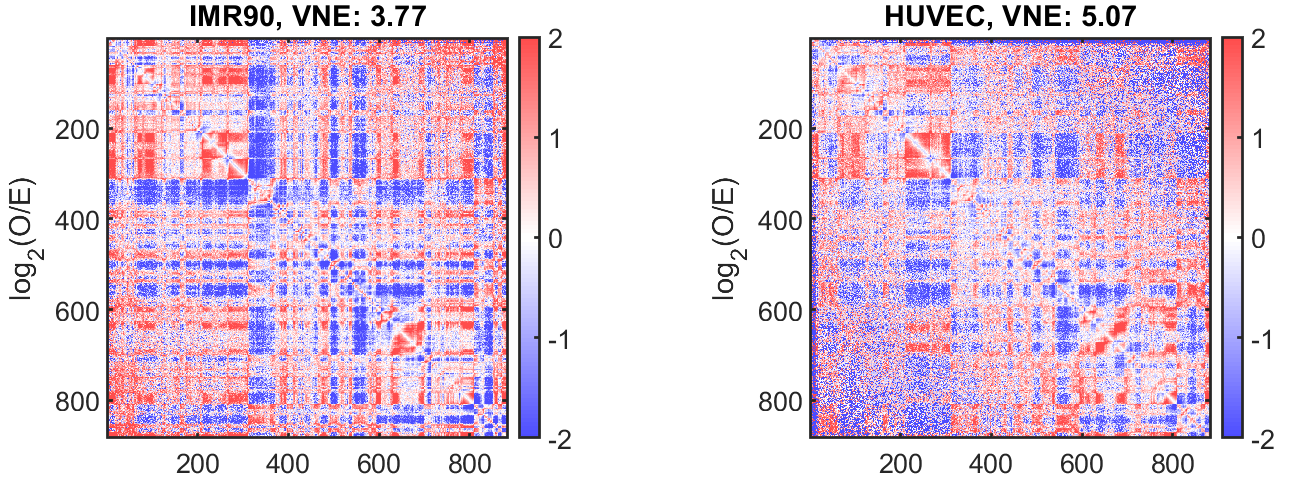

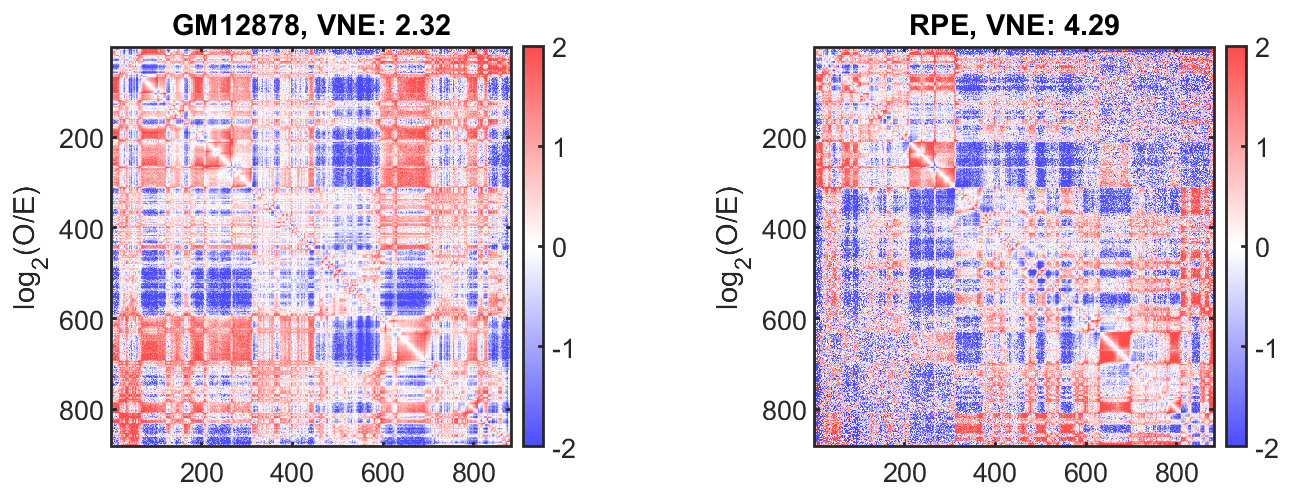

### Larntz-Perlman

close all
Data_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\myodData\myodData.mat';
Folder_Result = 'results\lpExampleResults';

lpExample(Data_Loc, Folder_Result);

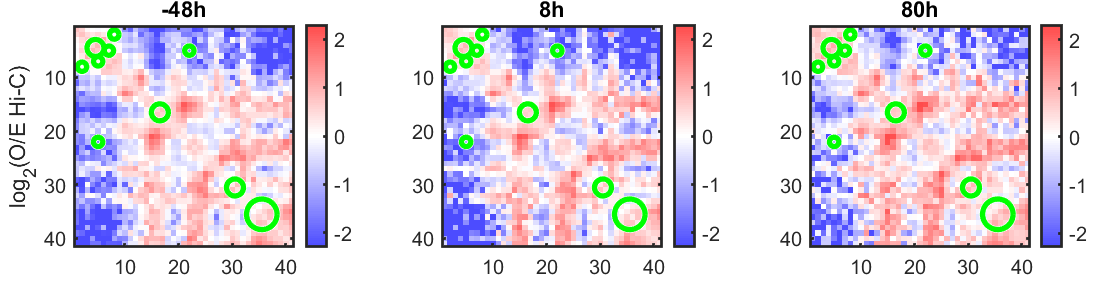

### Network Analysis

Data_Loc = '\\172.17.109.24\internal_4dn\projects\4DNvestigator_data\networkData\'; %%% data input folder
Folder_Result = 'results\networkExamplesResults'; %%% output result file name

networkExamples(Data_Loc, Folder_Result);